close all;
clear all;
rosshutdown;

Shutting down global node /matlab_global_node_81248 with NodeURI http://10.0.1.54:55754/


ip_TurtleBot = '10.0.1.57';    
ip_Matlab = '10.0.1.54'; 

setenv('ROS_MASTER_URI', strcat('http://', ip_TurtleBot,':11311'))
setenv('ROS_IP', ip_Matlab)

rosinit(ip_TurtleBot)

The value of the ROS_IP environment variable, 10.0.1.54, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_90042 with NodeURI http://10.0.1.54:55786/



TurtleBot_Topic.picam = "/raspicam_node/image/compressed";
image_sub = rossubscriber(TurtleBot_Topic.picam);


global focalLength;
global pixelSize;
global cameraHeight;
global centerPixel;
global leftColumnCrop;
global rightColumnCrop;
global upperRowCrop;
global lowerRowDrop;
%all units in mm or pixels
focalLength = 3.6;
pixelSize = 0.00567; %actual pixel size is 1.4microns, this is effective pixel size of compressed image
cameraHeight = 130;
centerPixel = [240, 320];
leftColumnCrop = 0;
rightColumnCrop = 640;
upperRowCrop = 360;
lowerRowDrop = 480;

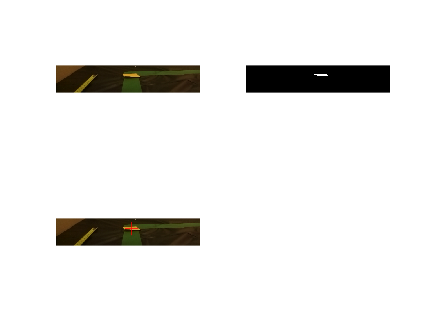

image = grabAndCleanUpImage(image_sub);
%image = imread('YellowTarget.png');
figure
subplot(221); imshow(image)
yellowImage = GetYellowPoints(image);
centroid = GetYellowCentroid(yellowImage);
subplot(223); imshow(image); hold on
plot(centroid(2), centroid(1), '+', 'MarkerSize', 10, 'Color',[1 0 0])
hold off

distanceComponents = CalcObjectDistance(centroid)

distanceComponents =    14.2683  503.2907


%130mm camera to ground distance
%350mm distance away

function image = grabAndCleanUpImage(image_sub)
    global leftColumnCrop;
    global rightColumnCrop;
    global upperRowCrop;
    global lowerRowDrop;
    image_compressed = receive(image_sub);
    image_compressed.Format = 'bgr8; jpeg compressed bgr8';
    rotatedImage = imrotate(readImage(image_compressed), 180);
    %eliminate the upper half of the image
    image = imcrop(rotatedImage, [leftColumnCrop, upperRowCrop, rightColumnCrop, lowerRowDrop]);
end

function yellowPoints = GetYellowPoints(originalImage)
    redLowerBound =200;% 
    redUpperBound =220;%
    greenLowerBound =145;% 
    greenUpperBound =160;%
    blueLowerBound =35;% 
    blueUpperBound =55;% 
    yellowPoints = redUpperBound>=originalImage(:,:,1) & originalImage(:,:,1)>=redLowerBound & originalImage(:,:,2)<=greenUpperBound & originalImage(:,:,2)>=greenLowerBound & originalImage(:,:,3)<=blueUpperBound & originalImage(:,:,3)>=blueLowerBound;
    subplot(222); imshow(yellowPoints)
end

function centroid = GetYellowCentroid(binaryImage)
    [y, x] = find(binaryImage);
    yMean = mean(y);
    xMean = mean(x);
    centroid = [round(yMean), round(xMean)];
end

function distanceComponents = CalcObjectDistance(centroidPixelPosition)
    global focalLength;
    global pixelSize;
    global cameraHeight;
    global centerPixel;
    global upperRowCrop;
    centroidPixelPositionYSigned = centroidPixelPosition(1) + upperRowCrop - (centerPixel(1));
    centroidPixelPositionXSigned = centroidPixelPosition(2) - (centerPixel(2));
    yPrime = pixelSize*centroidPixelPositionYSigned;
    xPrime = pixelSize*centroidPixelPositionXSigned;
    z = cameraHeight * focalLength / yPrime;
    x = xPrime * z / focalLength;
    distanceComponents = [x, z];
end